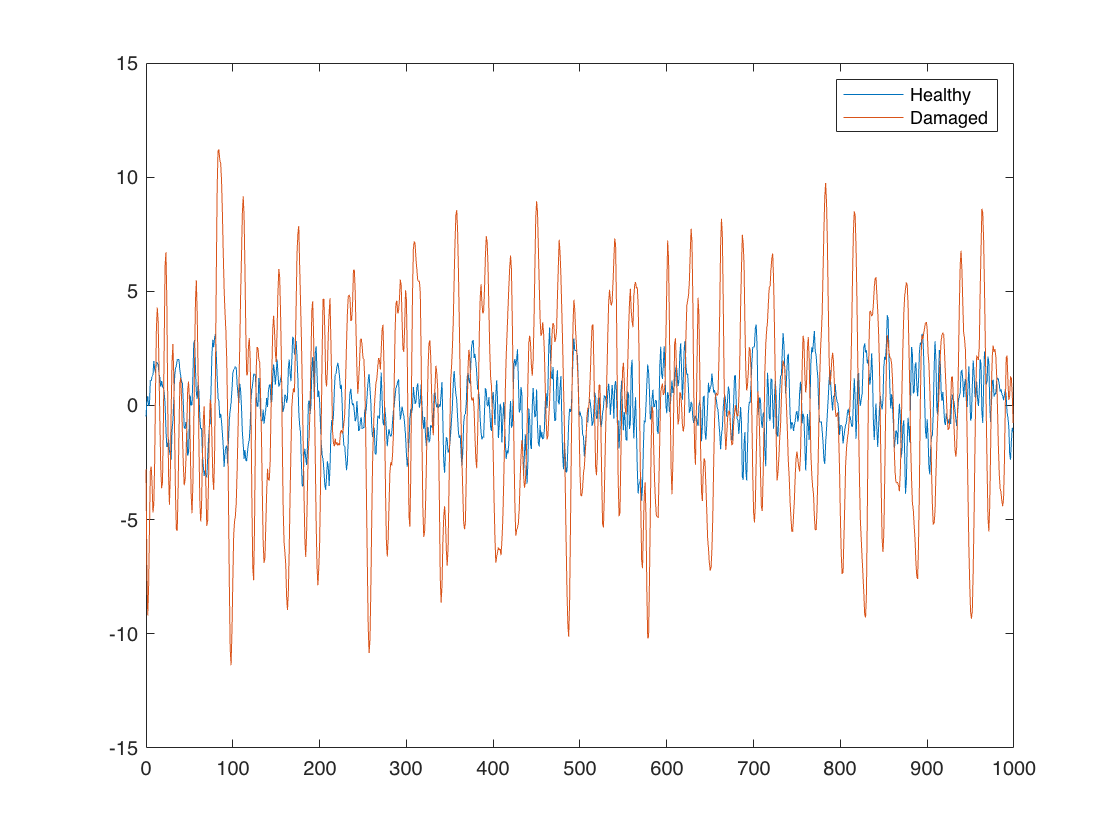

healthy = load("data/Healthy/H1.mat").AN10;
damaged = load("data/Damaged/D1.mat").AN10;

n = 1000;
fs = 40000;

omega = linspace(0,n,n+1);omega(end)=[];

healthy = healthy(1:n);
damaged = damaged(1:n);

plot(omega,healthy,"DisplayName","Healthy");
hold on;
plot(omega,damaged,"DisplayName","Damaged");
legend();
hold off;

addpath SSD/

comp1 = SSD(healthy,fs);
comp2 = SSD(damaged,fs);

addpath plotting/

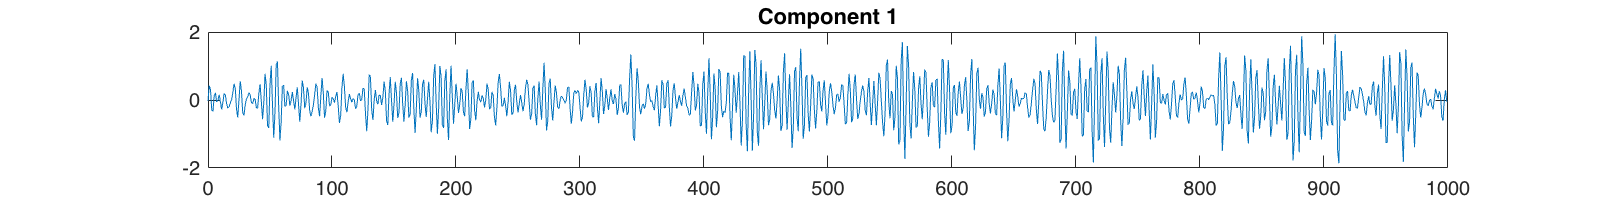

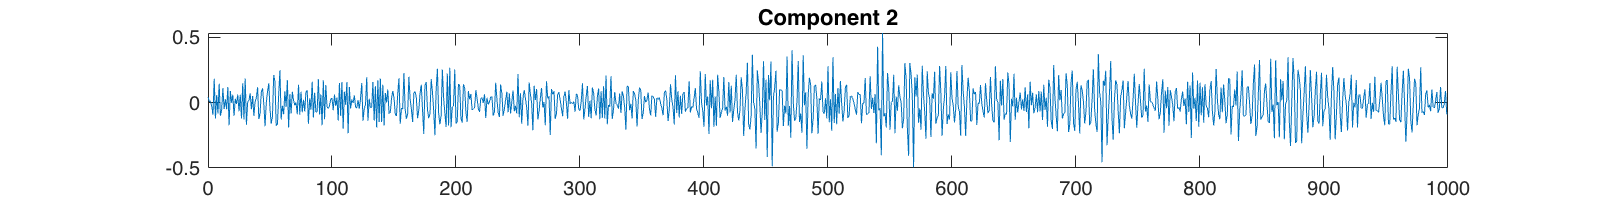

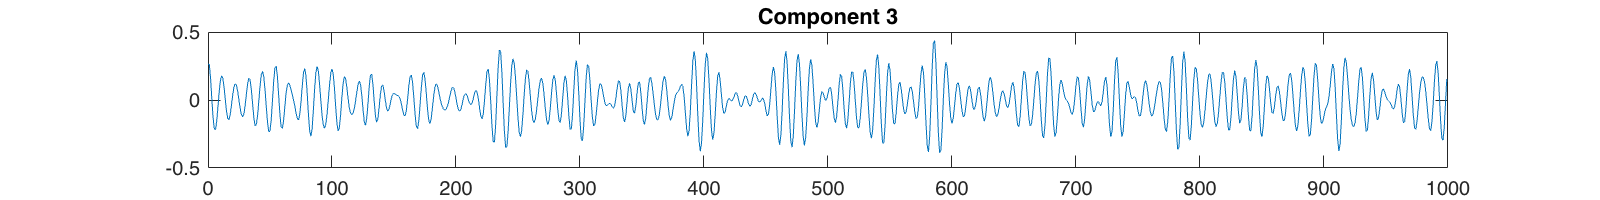

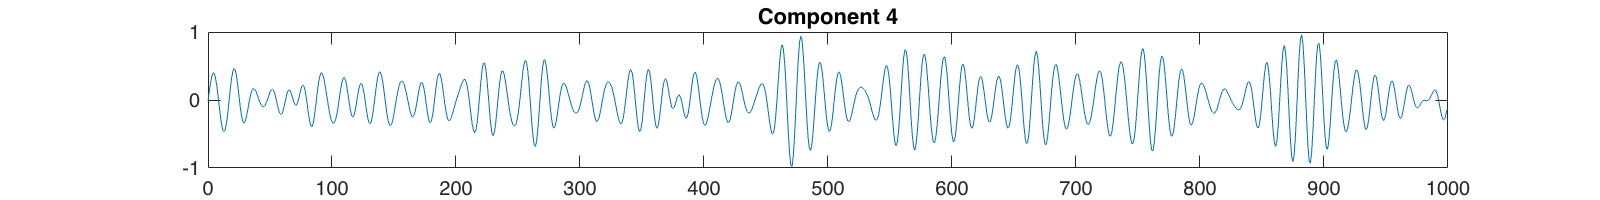

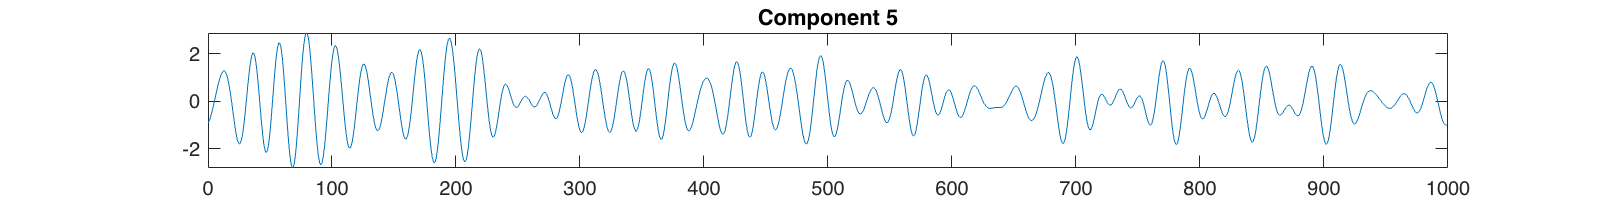

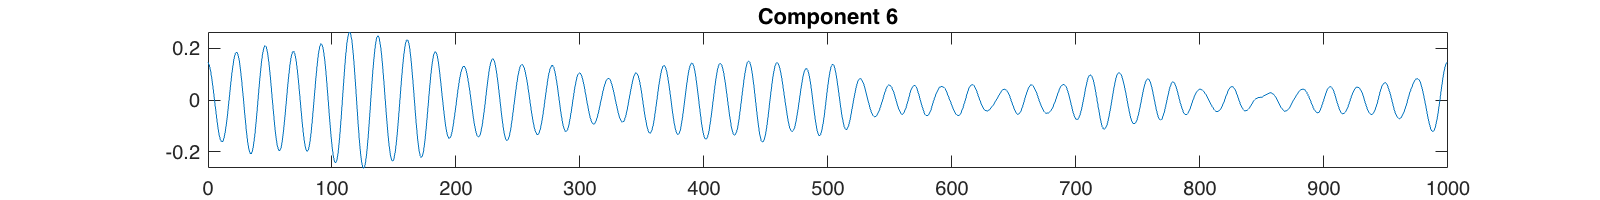

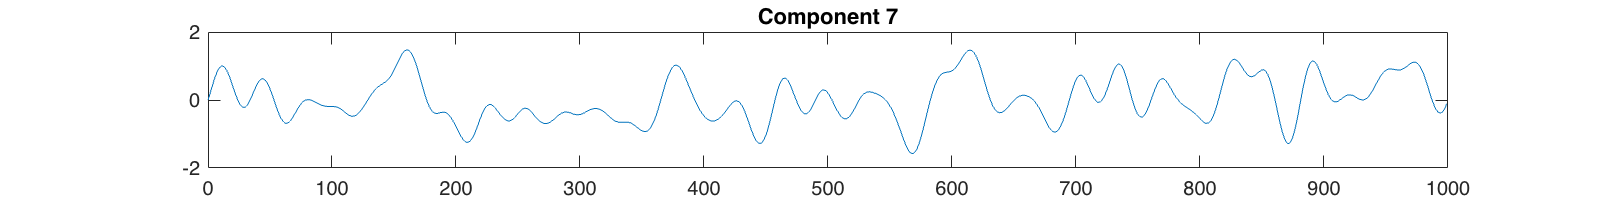

plot_SSD_components(omega, comp1);

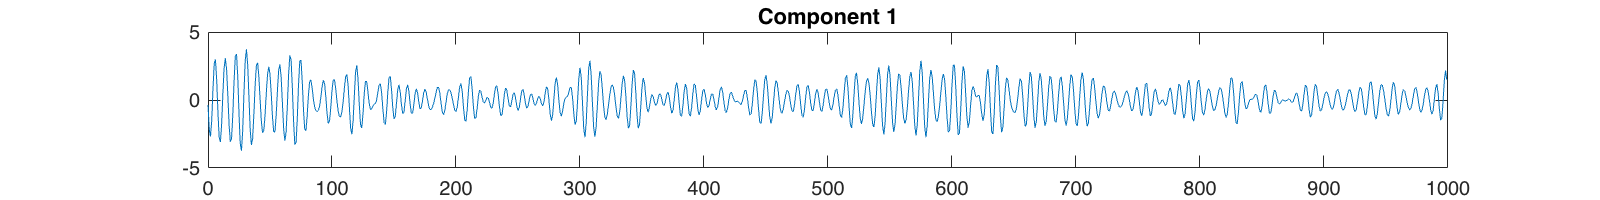

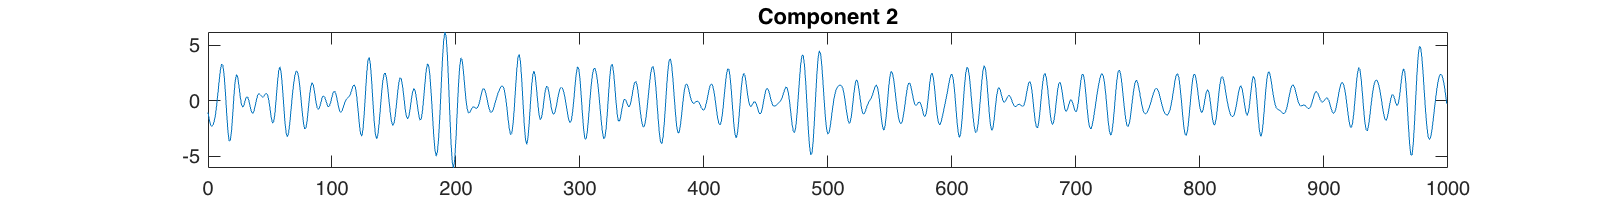

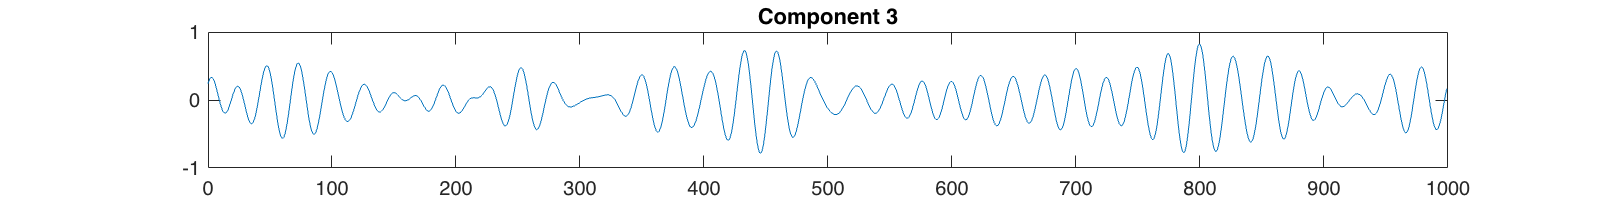

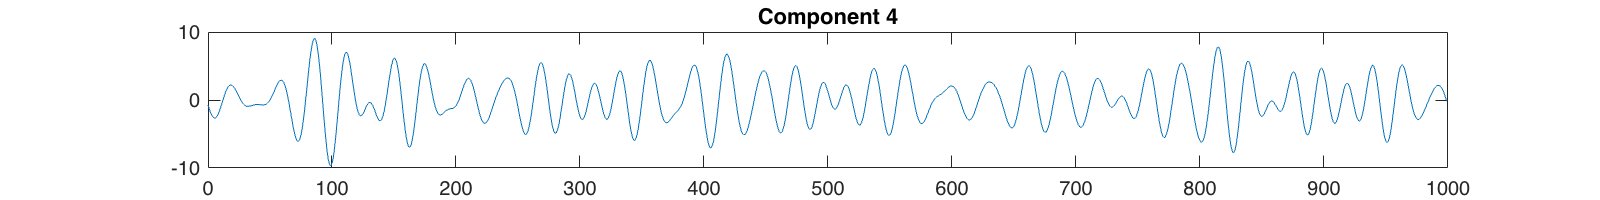

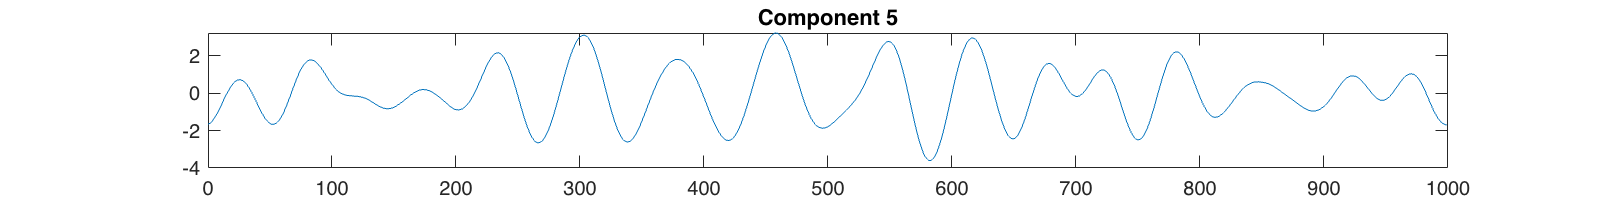

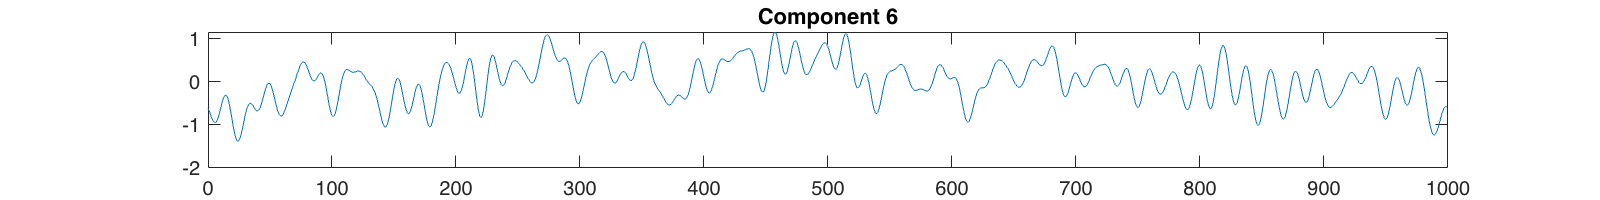

plot_SSD_components(omega, comp2);